# Example 3.1: Using function imadjust.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

Figure 3.3(a) is a digital mammogram image, f, showing a small lesion. 

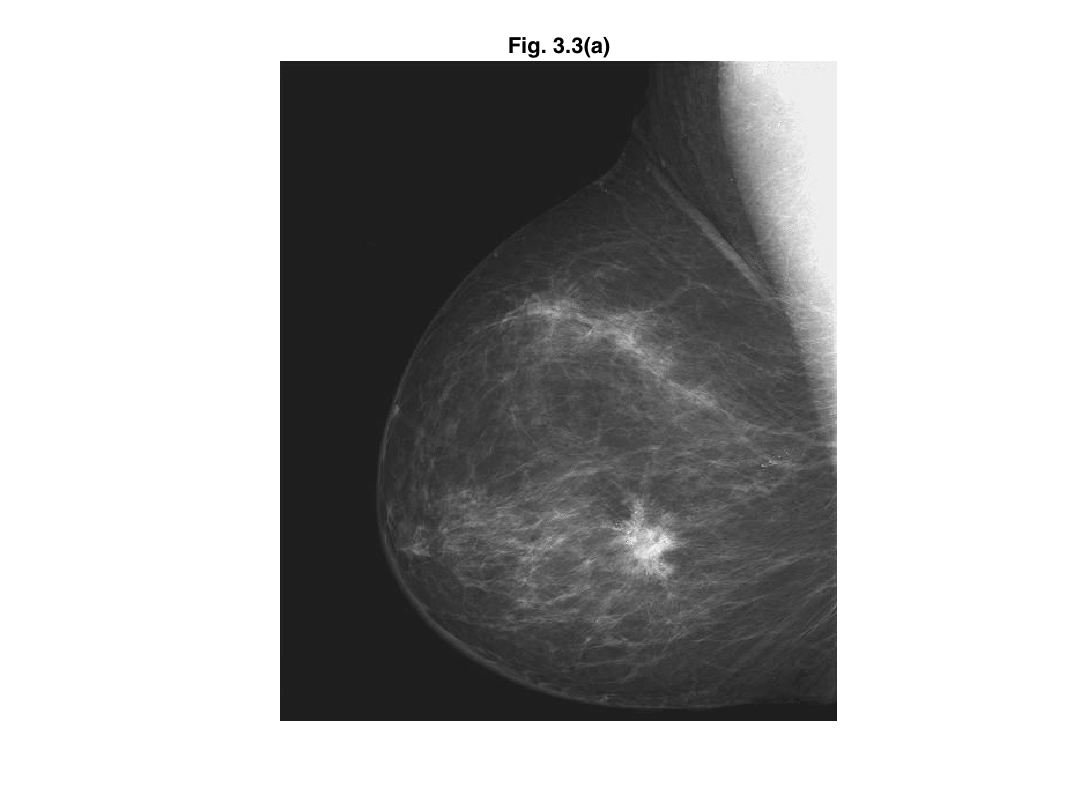

f = imread('breastXray.tif');

imshow(f)
title('Fig. 3.3(a)')

We obtained Fig. 3.3(b) using the commands

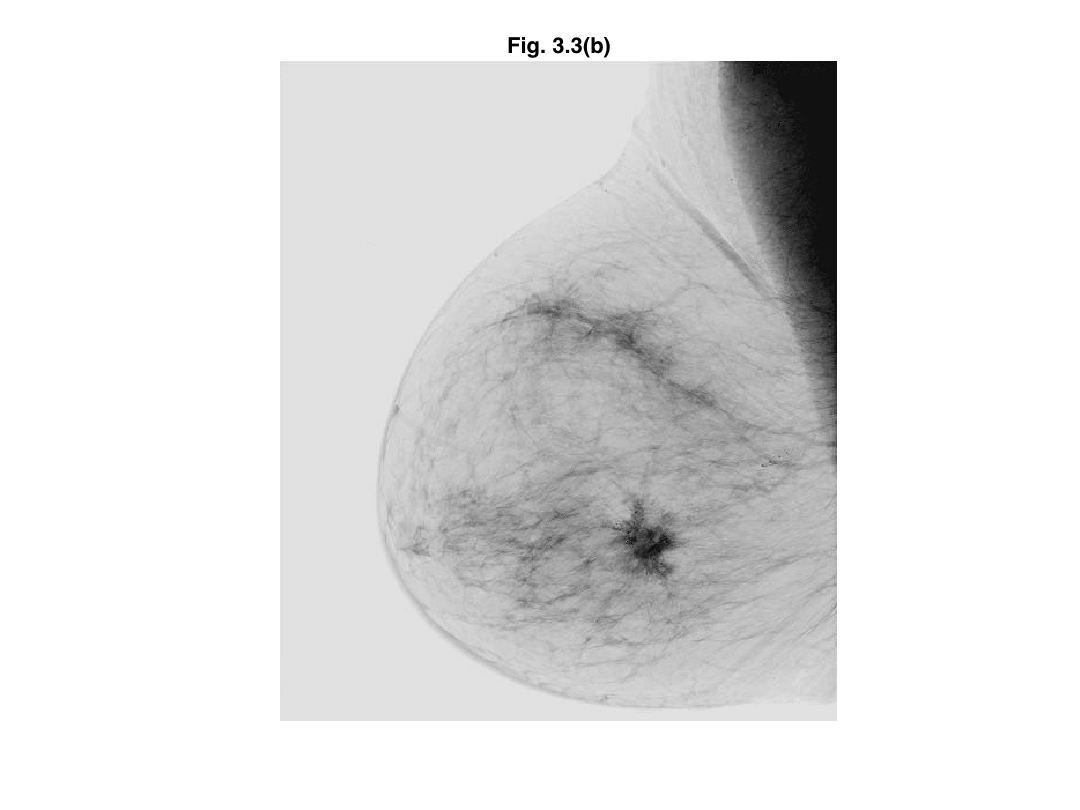

g1 = imadjust(f,[0 1],[1 0]);

imshow(g1) 
title('Fig. 3.3(b)')

This process, which is the digital equivalent of obtaining a photographic negative, is particularly useful for enhancing white or gray detail embedded in a large, predominantly dark region. Note, for example, how much easier it is to analyze the breast tissue in Fig. 3.3(b). The negative of an image can be obtained also using the Toolbox function imcomplement:

We obtained Fig. 3.3(c) using the command

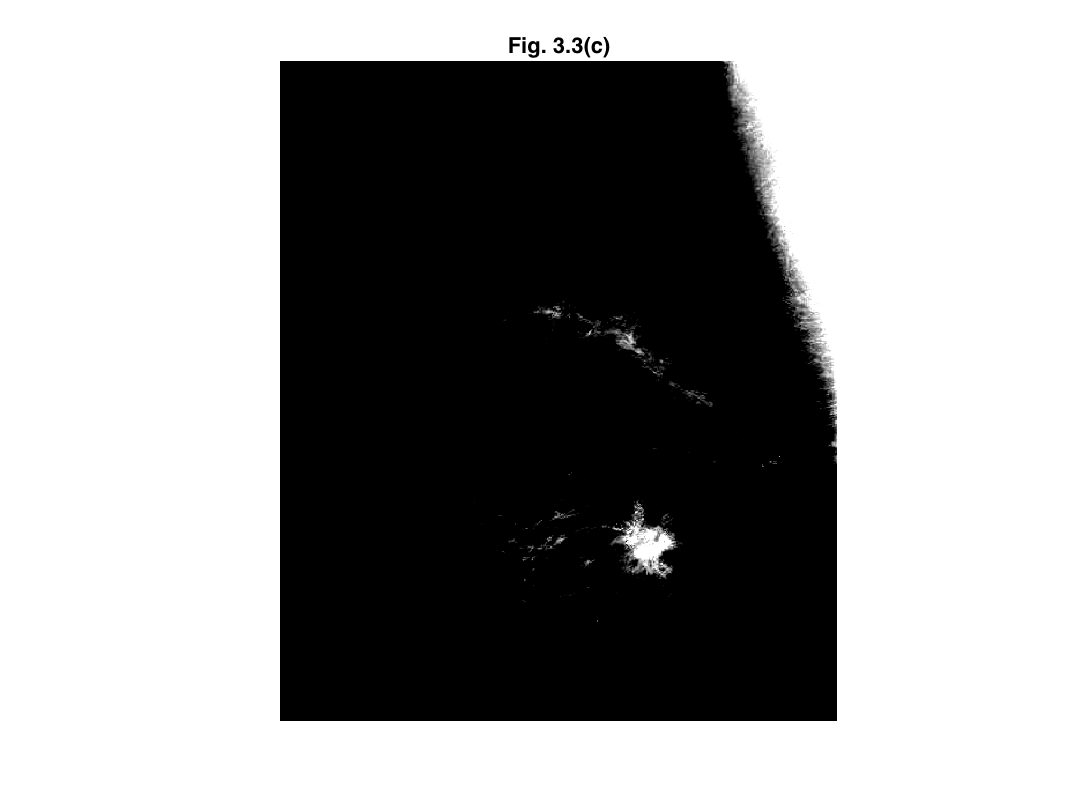

g2 = imadjust(f,[0.5 0.75],[0 1]);

imshow(g2)
title('Fig. 3.3(c)')

which expands the gray scale interval between 0.5 and 0.75 to the full [0, 1] range. This type of processing is useful for highlighting an intensity band of interest. Finally, using the command

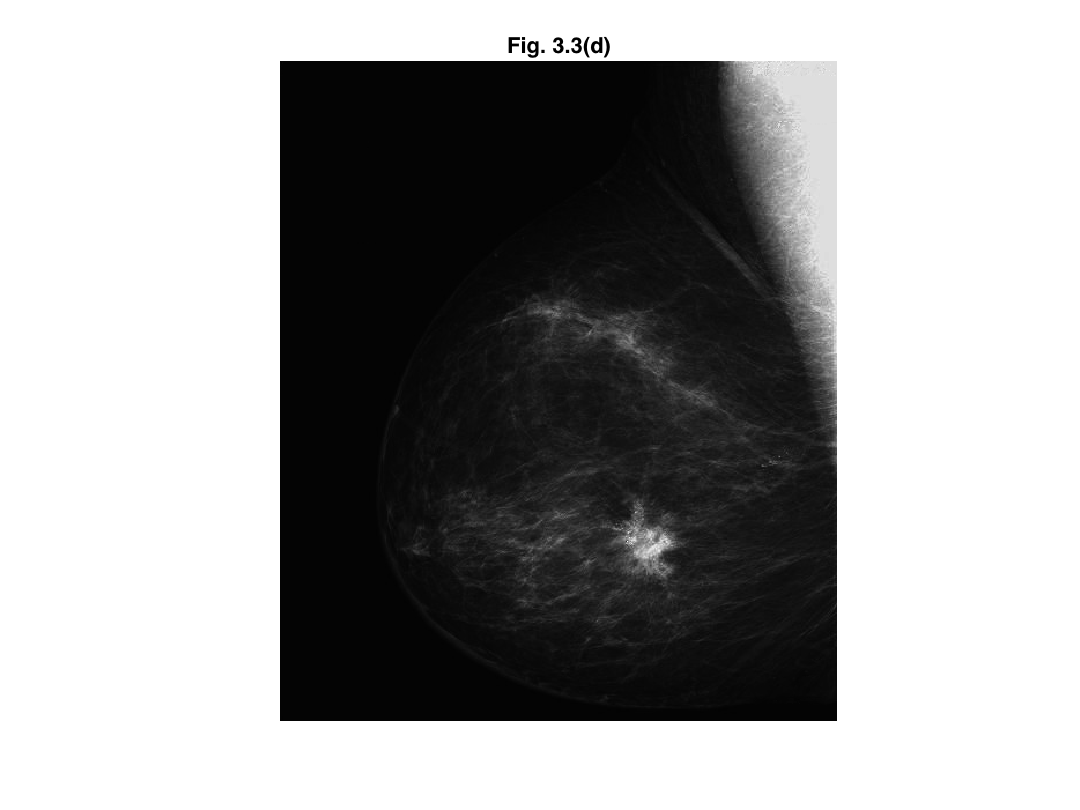

g3 = imadjust(f,[],[],2);

imshow(g3)
title('Fig. 3.3(d)')

produced a result similar to (but with more gray tones than) Fig. 3.3(c) by compressing the low end and expanding the high end of the gray scale [see Fig. 3.3(d)].

Sometimes, it is of interest to be able to use function imadjust "automatically," without having to deal with the low and high parameters discussed above. Function stretchlim can be used for this purpose; its basic syntax is

where LowHigh is a two-element vector of a lower and upper limit that can be used to achieve contrast stretching (see the following section for a definition of this term).

By default, values in LowHigh specify the intensity levels that saturate the bottom and top 1% of all pixel values in f. We use function stretchlim with function imadjust as follows:

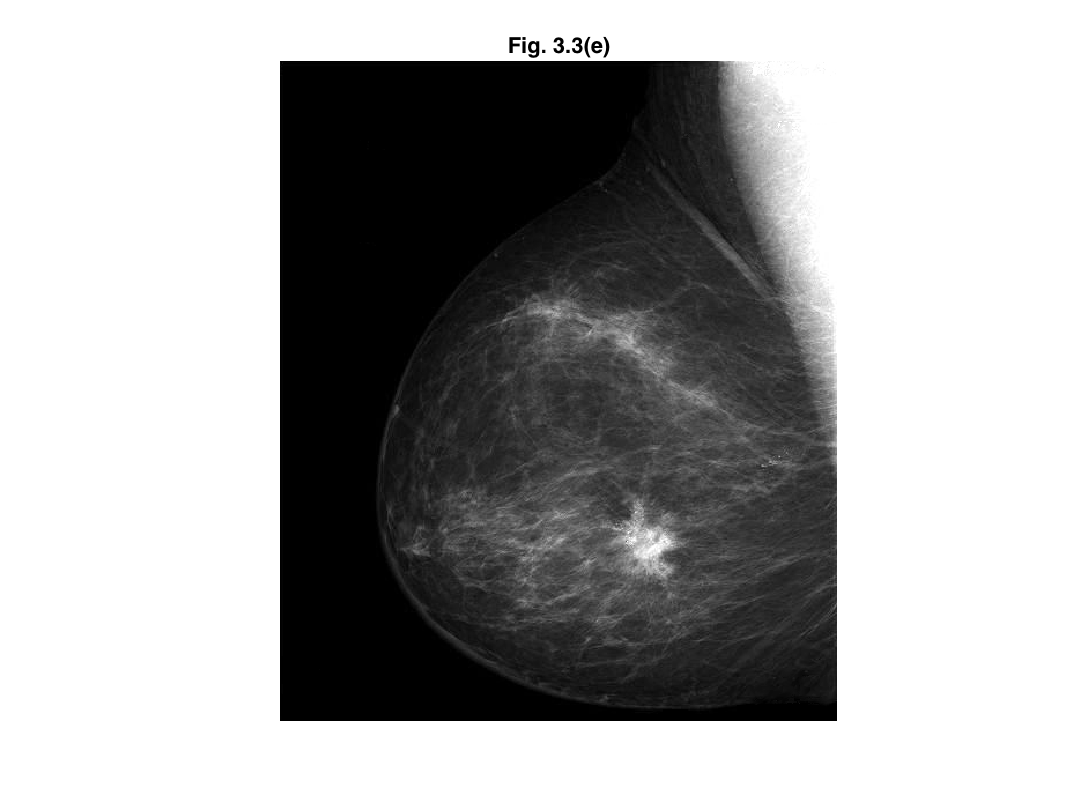

g4 = imadjust(f,stretchlim(f),[]);

imshow(g4)
title('Fig. 3.3(e)')

Figure 3.3(e) shows the result of performing this operation on Fig. 3.3(a). Observe the increase in contrast. Similarly, we obtained Fig. 3.3(f) using the command

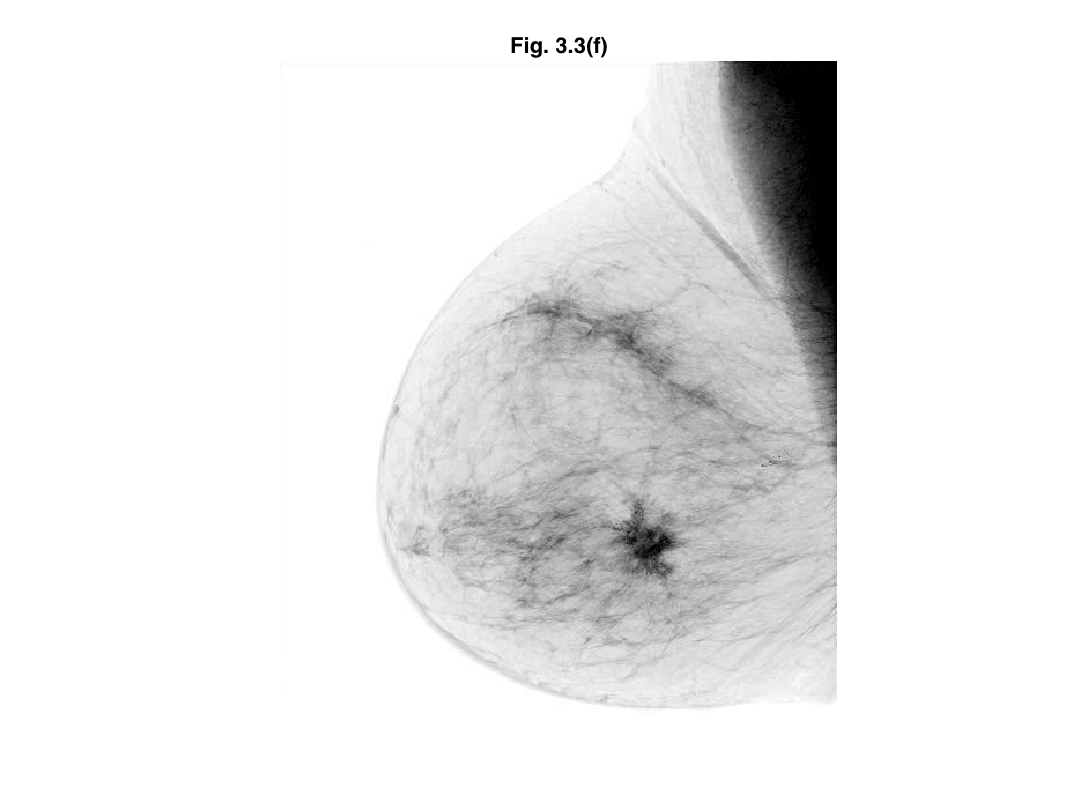

g5 = imadjust(f,stretchlim(f),[1 0]);

imshow(g5)
title('Fig. 3.3(f)')

As you can see by comparing Figs. 3.3(b) and (f), this operation enhanced the contrast of the negative image.